# enae404 hw07

vai srivastava

addpath("./.") % path to provided code
addpath("../../../code") % path to custom ENAE404 lib

## problem 3

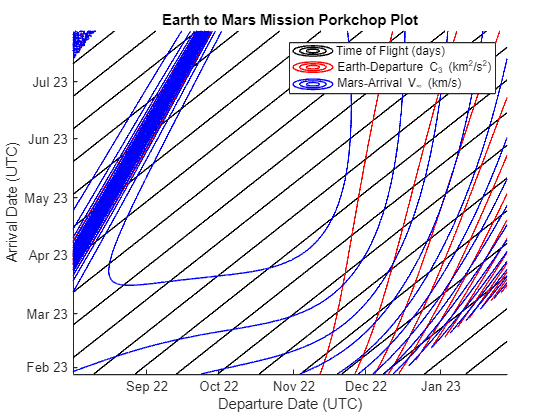

dep0 = [2022,8,1,12,0,0];
arr0 = [2023,1,28,12,0,0];
nDep = 400;
nArr = 400;
minTOF = 45;
maxTOF = 500;

depStartDN = datenum(dep0);
arrStartDN = datenum(arr0);
depEndDN = arrStartDN;
depDates = linspace(depStartDN, depEndDN, nDep);
arrEndDN = arrStartDN + (depEndDN - depStartDN);
arrDates = linspace(arrStartDN, arrEndDN, nArr);

[DEP, ARR] = meshgrid(depDates, arrDates);
TOF = (ARR - DEP);

valid = (TOF >= minTOF) & (TOF <= maxTOF);

C3 = nan(size(TOF));
VinfMars = nan(size(TOF));

for i = 1:numel(DEP)
    if ~valid(i)
        continue
    end

    dv_dep = datevec(DEP(i));
    dv_arr = datevec(ARR(i));
    jd_dep = Provided.ymdhms2jd(dv_dep(1), dv_dep(2), dv_dep(3), dv_dep(4), dv_dep(5), dv_dep(6));
    jd_arr = Provided.ymdhms2jd(dv_arr(1), dv_arr(2), dv_arr(3), dv_arr(4), dv_arr(5), dv_arr(6));
    tof_sec = (jd_arr - jd_dep)*86400;

    [RE, VE] = Provided.findEarth(jd_dep);
    [RM, VM] = Provided.findMars(jd_arr);

    [V1.short, V2.short, ~, ~] = SFD.solve_lambert(RE, RM, tof_sec, SFD.mu_Sun, false);
    [V1.long, V2.long, ~, ~] = SFD.solve_lambert(RE, RM, tof_sec, SFD.mu_Sun, true);

    Vinf_dep.short = V1.short - VE;
    Vinf_dep.long = V1.long - VE;
    Vinf_arr.short = V2.short - VM;
    Vinf_arr.long = V2.long - VM;

    short = norm(Vinf_dep.short)+norm(Vinf_arr.short);
    long = norm(Vinf_dep.long)+norm(Vinf_arr.long);

    if short < long
        C3(i) = norm(Vinf_dep.short)^2;
        VinfMars(i) = norm(Vinf_arr.short);
    else
        C3(i) = norm(Vinf_dep.long)^2;
        VinfMars(i) = norm(Vinf_arr.long);
    end
end

depDatesNum = depDates;
arrDatesNum = arrDates;

figure; hold on;
contour(depDatesNum, arrDatesNum, TOF, 20, 'k');
contour(depDatesNum, arrDatesNum, C3, 20, 'r');
contour(depDatesNum, arrDatesNum, VinfMars, 20, 'b');
legend('Time of Flight (days)', 'Earth‐Departure C_3 (km^2/s^2)', 'Mars‐Arrival V_{\infty} (km/s)');
title("Earth to Mars Mission Porkchop Plot");
xlabel('Departure Date (UTC)');
ylabel('Arrival Date (UTC)');
datetick('x','mmm yy','keeplimits');
datetick('y','mmm yy','keeplimits');